# MXB201 Solutions 6

### P7

(a) Find the least squares approximation of the function $f(x) = \cos(\pi x)$ over the interval $[-1,1]$ by a polynomial $p_2$ of degree 2.

syms x
P = [1 x x^2]

$$P = \left(\begin{array}{ccc} 1 & x & x^{2} \end{array}\right)$$

ip = @(u,v) int(u.*v, [-1,1])  % inner product

ip = function_handle with value:
    @(u,v)int(u.*v,[-1,1])

Q(1) = P(1) / sqrt(ip(P(1), P(1)))

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\cos\left(x\right)}{\sqrt{\pi }} & \frac{\sin\left(x\right)}{\sqrt{\pi }} \end{array}\right)$$

Q(2) = P(2) - ip(P(2), Q(1)) * Q(1); Q(2) = Q(2) / sqrt(ip(Q(2), Q(2)))

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{\sin\left(x\right)}{\sqrt{\pi }} \end{array}\right)$$

Q(3) = P(3) - ip(P(3), Q(1)) * Q(1) - ip(P(3), Q(2)) * Q(2); Q(3) = Q(3) / sqrt(ip(Q(3), Q(3)))

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,\left(x^{2}-\frac{1}{3}\right)}{4} \end{array}\right)$$

% check
ip(Q', Q)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

f = cos(Pi*x)

$$f = \cos\left(\pi \,x\right)$$

c = ip(f, Q)'

$$c = \left(\begin{array}{c} 0\\ 0\\ -\frac{3\,\sqrt{10}}{\pi^{2}} \end{array}\right)$$

Projf = Q * c

$$Projf = -\frac{9\,\sqrt{2}\,\sqrt{5}\,\sqrt{10}\,\left(x^{2}-\frac{1}{3}\right)}{4\,\pi^{2}}$$

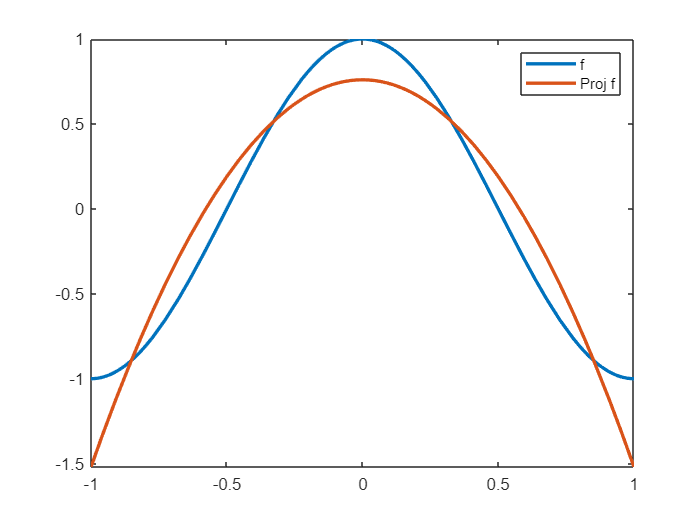

figure
fplot(f, [-1,1], LineWidth=2, DisplayName="f")
hold on
fplot(Projf, [-1,1], LineWidth=2, DisplayName="Proj f")
legend

(b) Compare the accuracy visually to the Taylor polynomial of degree 2.

Taylorf = series(f, x, order=3)

$$Taylorf = 1-\frac{x^{2}\,\pi^{2}}{2}$$

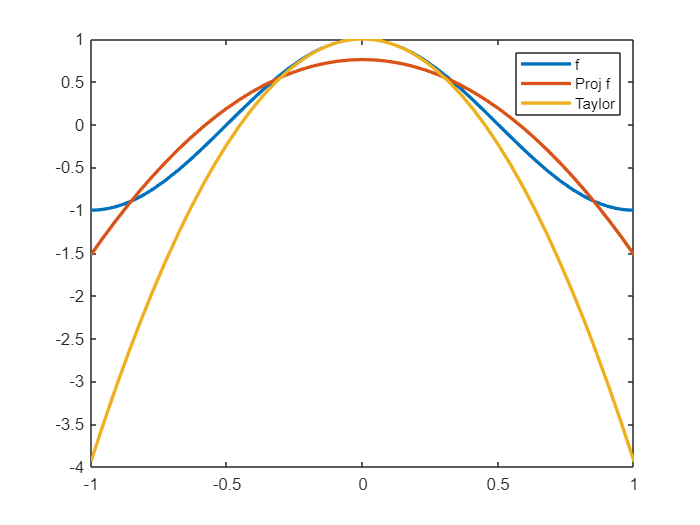

fplot(Taylorf, [-1,1], LineWidth=2, Displayname="Taylor")

### P8

(a) Find the least squares approximation of the function $f(x) = x^2$ over the interval $[-\pi,\pi]$ by a trigonometric polynomial $P_1$ of degree 1.

Pi = sym(pi);
Q = [1/sqrt(2*Pi), cos(x)/sqrt(Pi), sin(x)/sqrt(Pi)]  % we know the normalisation, or do the integrals if you prefer

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2\,\sqrt{\pi }} & \frac{\cos\left(x\right)}{\sqrt{\pi }} & \frac{\sin\left(x\right)}{\sqrt{\pi }} \end{array}\right)$$

ip = @(u,v) int(u.*v, [-pi,pi])

ip = function_handle with value:
    @(u,v)int(u.*v,[-pi,pi])

ip(Q', Q) % check

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

C = ip(x^2, Q)'

$$C = \left(\begin{array}{c} \frac{\sqrt{2}\,\pi^{5/2}}{3}\\ -4\,\sqrt{\pi }\\ 0 \end{array}\right)$$

P = Q * C

$$P = \frac{\pi^{2}}{3}-4\,\cos\left(x\right)$$

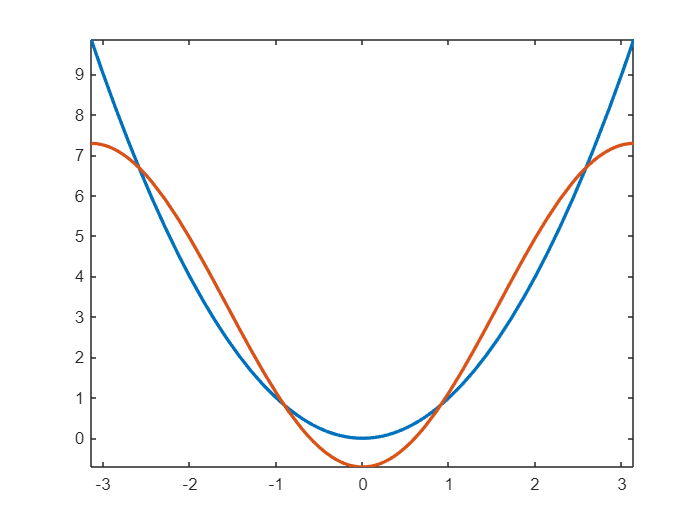

figure, fplot(x^2, [-pi,pi], LineWidth=2), hold on, fplot(P, [-pi,pi], LineWidth=2)